clear all
close all
%% minimum size of the PV system without the ESS
load('Irr_PA_mon.mat'); %%place near palermo 
load('load_profiles.mat');  
P_load = 2.5e3; %2.5 kW
rend_PV = 0.9; %90 efficiency by area (packaging i think) or this efficiency is the efficiecy of electric stuff, inverter and everything, we dont have solar panels with 90% efficiency. currently its about 15,17%   
start_time = 5;
end_time = 19;

P_pv = @(x,k,y,eta) max(0,eta*(k(3).*x.^2 + k(2).*x + k(1)).*y); %% implicit functions for determming the power produced, given the irradiance 
%% x is the irradiance, k is the material, y = nominal power of the PV plant, eta = efficiency of the PV plant  
k = [-0.0138 0.000898 0;... %% this is mono
    -0.074 0.001 0;... %% this is for amorphos silicon
    -0.0187 0.0012 -0.0000004]; %% other one 

tech = {'mc-Si','a-Si','CIGS'};
%% graphs for different technologies
%% 



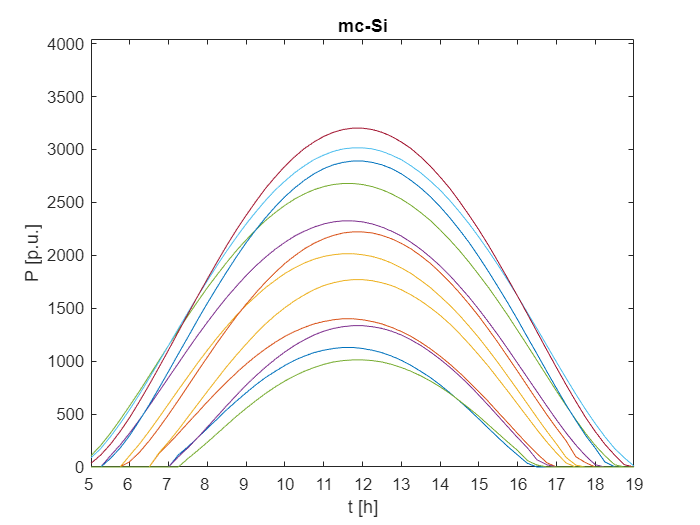

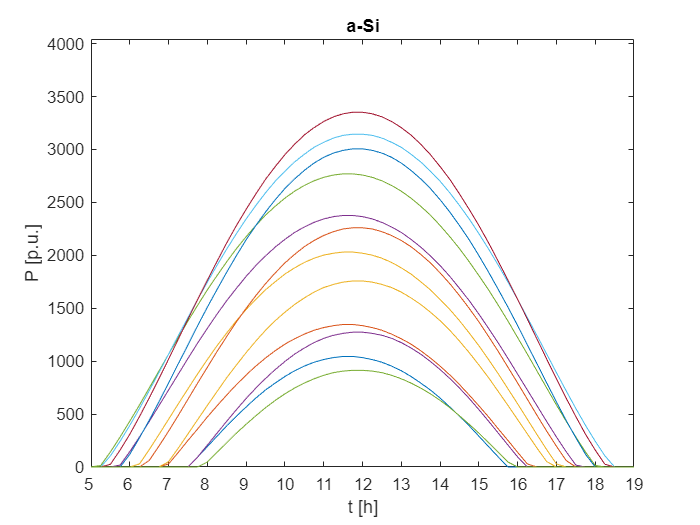

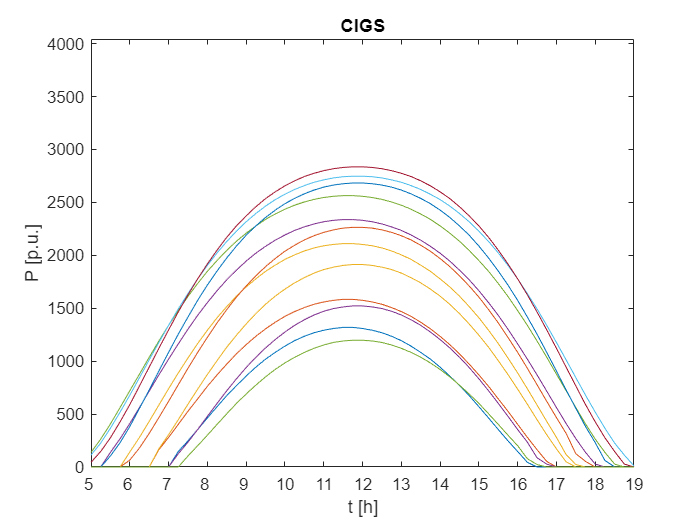

%%
Pn = 4043.91;
for i = 1:1:3,
    prod_p = P_pv(Irr_PA_mon,k(i,:),Pn,rend_PV);
    figure
    plot(prod_p)
    set(gca,'YLim',[0 Pn])
    set(gca,'XLim',[1 size(Irr_PA_mon,1)])
    set(gca,'XTick',[1:4:57])
    set(gca,'XTickLabel',[5:1:19])
    xlabel('t [h]')
    ylabel('P [p.u.]')
    title(tech(i))
end

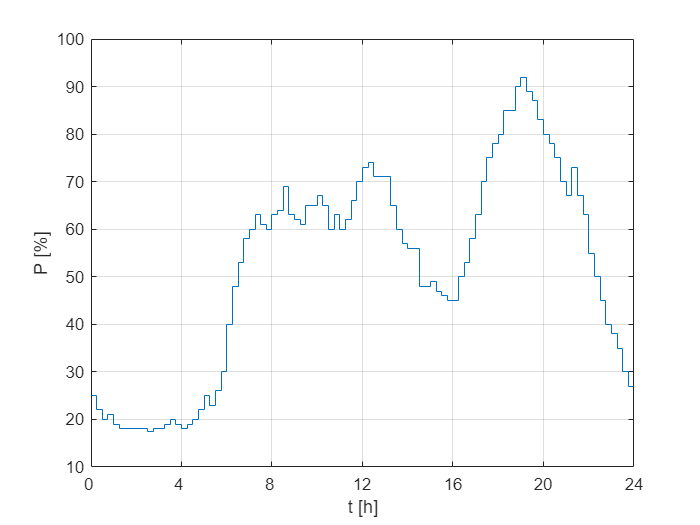

%%
figure
stairs([residential;residential(end)])
set(gca,'XLim',[1 length(residential)+1]);
set(gca,'XTick',[1,(4*4+1):4*4:96,97]);
set(gca,'XTickLabel',[0:4:24]);
xlabel('t [h]')
ylabel('P [%]')
grid on   %% this is the load

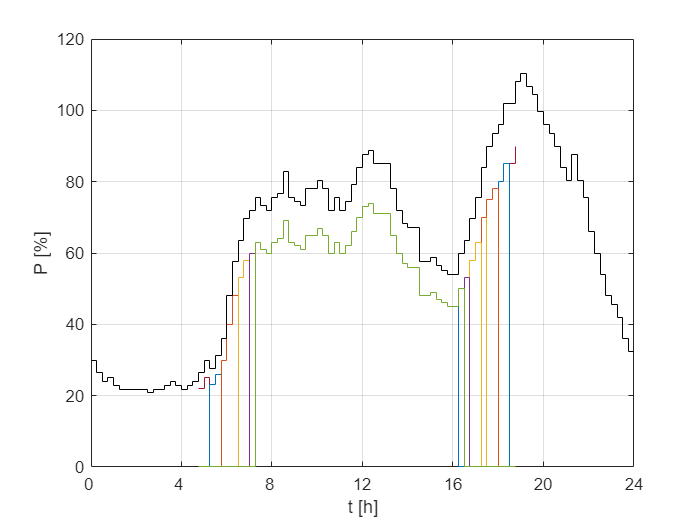



%% irradiance is in [5am,7pm]
res_load_pu = repmat(residential(start_time*4:1:end_time*4),1,12);
                     %bringing out the value of residential load at that
                     %time and basically creating 12 column matrix out of
                     %it 
res_load_pu(Irr_PA_mon == 0) = zeros(size(find(Irr_PA_mon == 0)));
                                               %converts the non zero to zero and zero to one   
                                          %find finds out the index of all the zero elements which are actually the irradiance in the original dataset
                                     %size sizes the number of elements    
                                %zeroes are converting the size number and throwing that many zeroes  

         %Basically you are getting a matrix of load in the PV format, if
         %at 8:15 my load is 100 then then if my pv isnt active, if that is
         %zero then obviosly my load is zero too. 
figure
stairs([start_time*4:1:(end_time*4)],res_load_pu)
hold on
stairs([residential;residential(end)].*1.2,'k')
set(gca,'XLim',[1 length(residential)+1]);
set(gca,'XTick',[1,(4*4+1):4*4:96,97]);
set(gca,'XTickLabel',[0:4:24]);
xlabel('t [h]')
ylabel('P [%]')
grid on
hold off %% marking the pv window %% black line is not more, its just shifted for visualisation 

res_load = res_load_pu.*P_load./100;
             %load*capacity/100 % how much load can be supported by your PV 
%%
irr = reshape(Irr_PA_mon,[],1);  %reshaping the matrix in another vetor/matrix
p_load = reshape(res_load,[],1); % column after column 

options = optimoptions('fmincon','Algorithm','interior-point','Display','none');
                       %Solver name %Option chosen #chosen 
self_cons_thres = [.5 .6 .7 .8 .9 1]; %usually we would like to take 80% as the self consumption 
for ii = 1:length(tech), %lenght of tech is 3, meaning we are running a loop in that matrix 
    for jj = 1:length(self_cons_thres), %another loop running the self consumption thres, basically jj takes on the values of every threshold for one technology, then the technology changes 
        tic
        [y(ii,jj), fval, exitflag(ii,jj)] = fmincon(@(x) -x, 1,[],[],[],[],0,[],@(x) mycon(x,p_load,irr,k(ii,:),rend_PV,self_cons_thres(jj)),options);
        etime(ii,jj) = toc;                 %here im finding the minimum of -x, which is max of x(x is the  provided the contraint which is mycon(non linear constraint - self consumpti on) 
    end 
end                                                                         
%in the above fucntion we are trying to find out the nominal value of PV
%which is actually your maximum value produced by your PV (with a contraint
%of self thres)
%consumption and technology. Y is the matrix with 
clear fval %% Then I am calculating the minimum PV size 

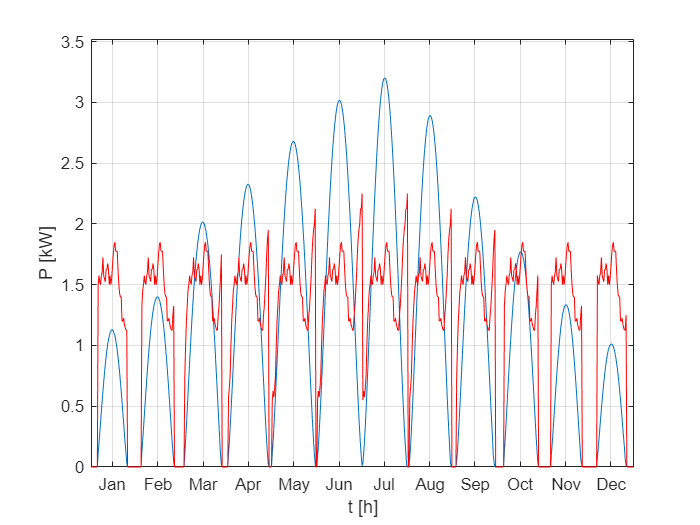

a = datenum('01/01/2017');
for i = 1:12,
    [n , month_label{i}] = month(a + 31*(i-1));
end
clear a
tech_sel = 1; %choosing the first technology
% self_cons_thres = [.5 .6 .7 .8 .9 1];
self_cons_comp = [.8 1];
figure
plot(P_pv(irr,k(tech_sel,:),y(tech_sel,find(self_cons_thres == self_cons_comp(1))),rend_PV)./1e3)
                            %nominal power of that particular technology
                            %and self consumption which is 80%
% we are trying to plot the power for each month and then we have the y which is nominal power 
hold on
plot(p_load./1e3,'r')
set(gca,'XLim',[1 length(p_load)]);
set(gca,'YLim',[0 1.1*max(max(P_pv(irr,[-0.0138 0.000898 0],y(tech_sel,find(self_cons_thres == self_cons_comp(2))),rend_PV)),max(P_pv(irr,k(tech_sel,:),y(tech_sel,find(self_cons_thres == self_cons_comp(1))),rend_PV)))]/1e3)
set(gca,'XTick',[28:57:12*57]);
set(gca,'XTickLabel',month_label);
xlabel('t [h]')
ylabel('P [kW]')
grid on
hold off

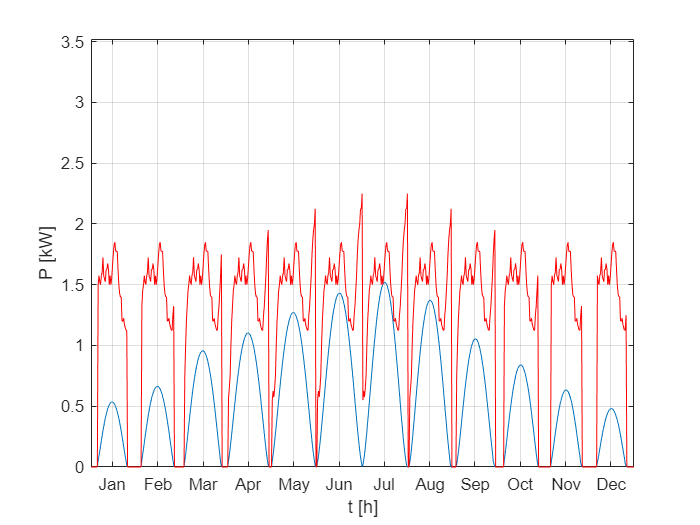

figure
plot(P_pv(irr,k(tech_sel,:),y(tech_sel,find(self_cons_thres == self_cons_comp(2))),rend_PV)./1e3)
hold on
plot(p_load./1e3,'r')
set(gca,'XLim',[1 length(p_load)]);
set(gca,'YLim',[0 1.1*max(max(P_pv(irr,k(tech_sel,:),y(tech_sel,find(self_cons_thres == self_cons_comp(2))),rend_PV)),max(P_pv(irr,k(tech_sel,:),y(tech_sel,find(self_cons_thres == self_cons_comp(1))),rend_PV)))]/1e3)
set(gca,'XTick',[28:57:12*57]);
set(gca,'XTickLabel',month_label);
xlabel('t [h]')
ylabel('P [kW]')
grid on
hold off

%energy storage system 
for jj = 1:length(self_cons_thres),
    for ii = 1:length(tech),
        a = P_pv(irr,k(ii,:),y(ii,jj),rend_PV) - p_load;
        %power produced by the photovoltaic plant - pload 
        %
        a(a<0) = zeros(size(find(a<0)));
        % for all the values where a is negative, make it zero 
        max_P_stg(ii,jj) = max(a)/1e3; 
                           %returns the maximum of each column then divide,
                           %basically this means that we are see where the
                           %PV crosses the load and then taking the maximum
                           %value of that area 
        max_E_stg(ii,jj) = max(sum(reshape(a,size(Irr_PA_mon)))./4)/1e3;
                           %same goes for calculating the energy 
        clear a
    end
end

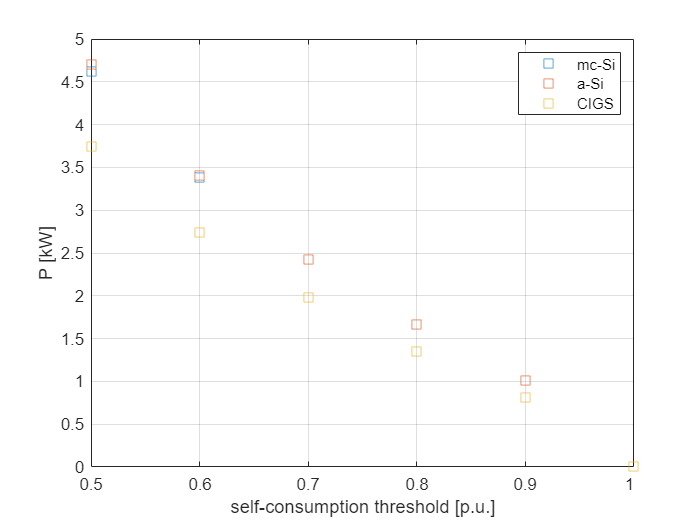

%Now we will just the plot those maximum values and then we are done with
%it. 

figure
plot(max_P_stg','Marker','s','MarkerSize',7,'LineStyle','none')
legend(tech)
set(gca,'XTick',[1:1:length(self_cons_thres)])
set(gca,'XTickLabel',self_cons_thres)
xlabel('self-consumption threshold [p.u.]')
ylabel('P [kW]')
grid on

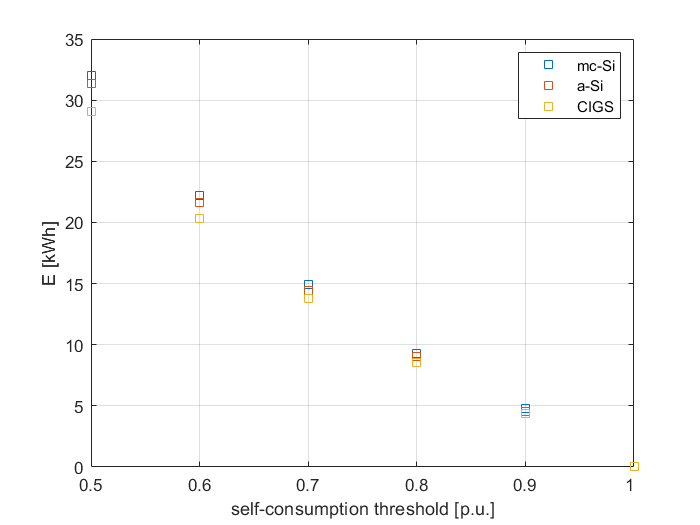

figure
plot(max_E_stg','Marker','s','MarkerSize',7,'LineStyle','none')
legend(tech)
set(gca,'XTick',[1:1:length(self_cons_thres)])
set(gca,'XTickLabel',self_cons_thres)
xlabel('self-consumption threshold [p.u.]')
ylabel('E [kWh]')
grid on